# RunTest Example for The Neural Network Learning Tool for Dual-Level Dynamic System Modeling (DDSM)

clear
close all
clc


## Initialization and Load Data

SystemOrder=1;
Maximum_Dimension=2;
SystemStateDimension=2;
tol = 0.2;
maximum_entropy=60;
NeuronNum_switch=10;
NeuronNum_single=100;
TF='ReLu';
timetic=3;
e=1.5e-5; % Expected Merged Tolerence
VerificationNum=20;
VerificationDuration=1000;
TrainingStateDimension=1;
InitialBound=[-46 -44;-3.1 -2];
VerificationU_input=[];
% Abstraction
AbstractionNum=400;
AbstractionDuration=200;
% Decrease Self LoopNum
SelfLoopNum=100;
Mode = 'Select Dimension';
idx = 2 ;
Name='Angle';
SimulationInputMode='None';
InitialSimulationBound='';

Ini = initialize(SystemOrder,Maximum_Dimension,SystemStateDimension,tol,maximum_entropy,NeuronNum_switch,NeuronNum_single,TF,timetic,e,VerificationNum,VerificationDuration,TrainingStateDimension, InitialBound,VerificationU_input,AbstractionNum,AbstractionDuration,SelfLoopNum,Mode,idx,Name);


## Load Data

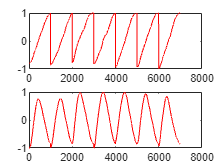

load('DataSet/Angle','demos','dt');
for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
end

[xsn,xsnu,tn,input_ps,output_ps,coeff,mu]=Ini.initializingdata(TrajData);
Ini=updateInitial(Ini,coeff,mu,input_ps,output_ps);
figure
for i = 1:size(xsn,1)
    subplot(size(xsn,1),1,i)
    plot(1:size(xsn,2),xsn(i,:),'r')
    hold on
end

## Neural Hybrid System Learning

NHS1=NHS(xsn,tn,Ini);

Starting Maximum Entropy Partitioning with epsilon=60
Number of Partitions 1
Elapsed time is 0.018974 seconds.
Number of Partitions 2
Elapsed time is 0.017014 seconds.
Number of Partitions 3
Elapsed time is 0.012413 seconds.
Number of Partitions 4
Elapsed time is 0.009490 seconds.
Number of Partitions 4
Elapsed time is 0.010894 seconds.
Number of Partitions 4
Elapsed time is 0.011359 seconds.
Number of Partitions 5
Elapsed time is 0.010175 seconds.
Number of Partitions 6
Elapsed time is 0.011429 seconds.
Number of Partitions 7
Elapsed time is 0.009093 seconds.
Number of Partitions 7
Elapsed time is 0.008904 seconds.
Number of Partitions 8
Elapsed time is 0.009323 seconds.
Number of Partitions 8
Elapsed time is 0.000015 seconds.
Number of Partitions 8
Elapsed time is 0.013550 seconds.
Number of Partitions 9
Elapsed time is 0.012356 seconds.
Number of Partitions 10
Elapsed time is 0.010053 seconds.
Number of Partitions 11
Elapsed time is 0.008885 seconds.
Number of Partitions 11
Elapsed 

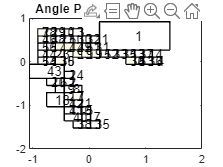

SamplesnPartitionsPlot(obj,xsn)
PoltDataPartition(NHS1)

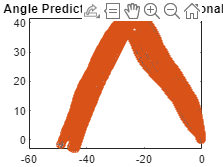

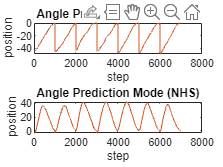

PredictionPlot(NHS1,xsn,tn)